edges = [0 .3 .5 1];
values = [1 1 0 0];
% 12+1 taps, edges, values
b = firpm(14,edges,values);
stem(b)
w = linspace(0,2*pi,500);
H = freqz(b, 1, w);
plot(w, abs(H));

% homework 5
N = 15

N = 15

w = 2*pi/15*[0:N-1];
%
A = (w <= pi/3) | (w >= 2*pi - (pi/3))

A = 1×15 logical array
   1   1   1   0   0   0   0   0   0   0   0   0   0   1   1


%
M = (N-1)/2;
ph = M*w;
H = A.*exp(-1j*ph);
h = ifft(H);
h = real(h)

h =     0.0581    0.0000   -0.0667   -0.0777   -0.0000    0.1419    0.2777    0.3333    0.2777    0.1419    0.0000   -0.0777   -0.0667   -0.0000    0.0581


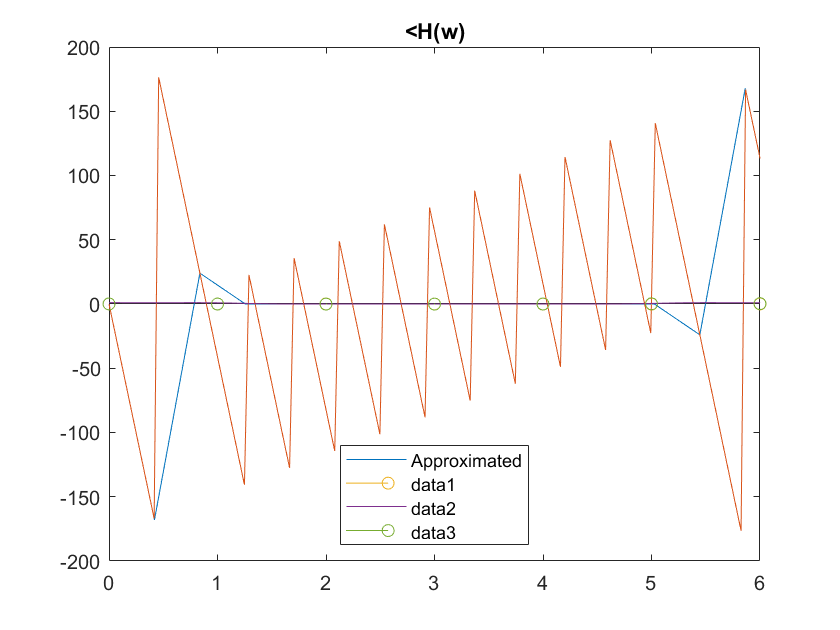

stem(0:1:14,h);

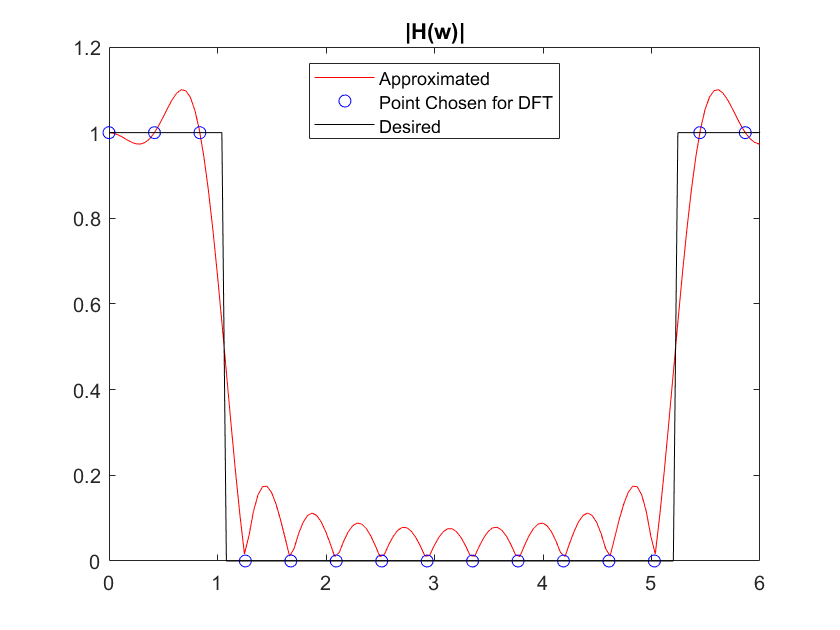

wfine = (2*pi/151)*[0:150];
Hout = freqz(h,1,wfine);
figure()
plot(wfine, abs(Hout),'r');
hold on;
plot(w, A, 'bo')
Ad = (wfine <= pi/3) | (wfine >= 2*pi - (pi/3));
plot(wfine, Ad, 'Color','black')
hold off
title('|H(w)|')
xlim([0 6])
legend('Approximated','Point Chosen for DFT','Desired','Location','north')

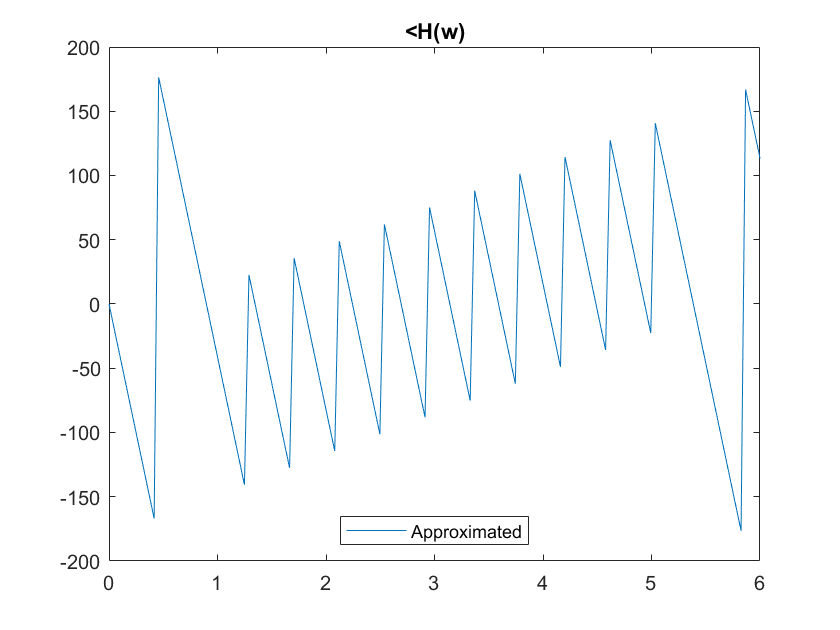


% now phase response
h = ifft(H);
h_ph = angle(h);
wfine = (2*pi/151)*[0:150];
Hout = freqz(h,1,wfine);
figure()
plot(wfine, angle(Hout)/(pi/180))
title('<H(w)')
xlim([0 6])
legend('Approximated','Location','south')